Wheel Calibration - Motor Constants Calculation:

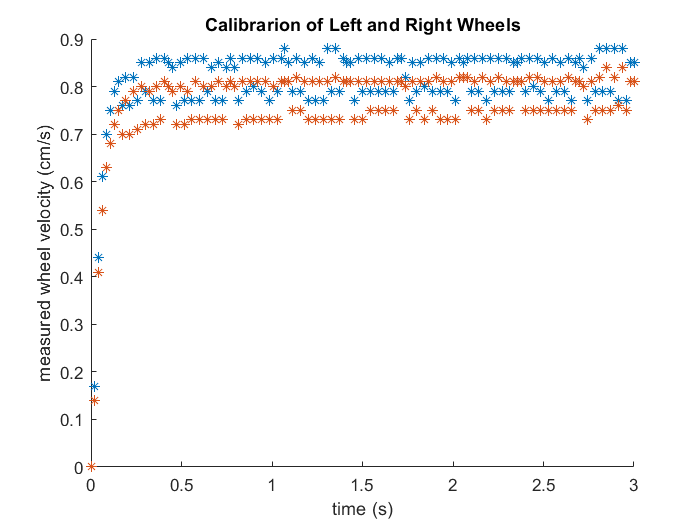

% **We loaded data manually from "wheel-calibration-4.csv" to get csv to output the correct format

% Separate left and right wheel velocity data and plot over time
wheel_time = linspace(0, 3, 141)';
l_wheel = wheelcalibration4(:,1);
r_wheel = wheelcalibration4(:,2);

clf; hold on;
plot(wheel_time, l_wheel, "*"); plot(wheel_time, r_wheel, "*");
title("Calibrarion of Left and Right Wheels");
xlabel("time (s)"); ylabel("measured wheel velocity (cm/s)");

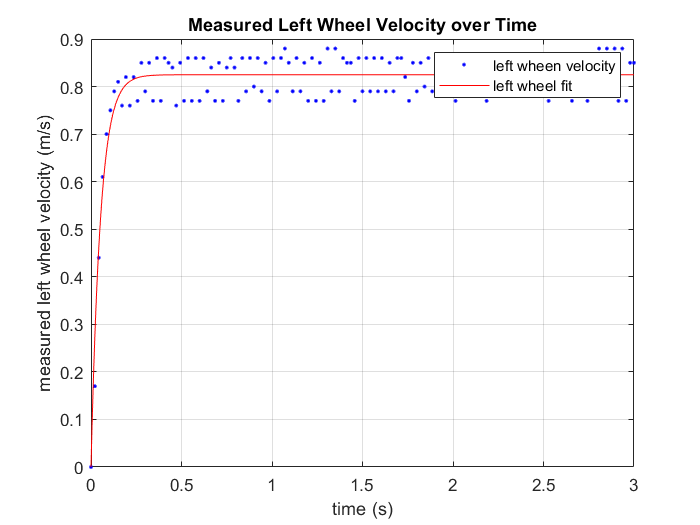

left_constants =      General model:
     left_constants(x) = (K*300)*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       K =    0.002749  (0.002727, 0.002772)
       T =     0.05256  (0.04614, 0.05898)


% Plot curve fitting data and output motor constants
[left_constants] = createLWheelFit(wheel_time, l_wheel)

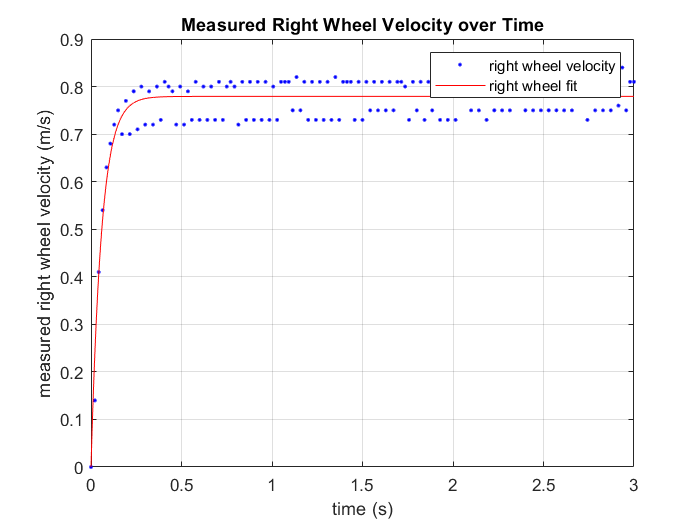

right_constants =      General model:
     right_constants(x) = (K*300)*(1-exp(-(1/T)*x))
     Coefficients (with 95% confidence bounds):
       K =    0.002598  (0.002576, 0.002619)
       T =     0.05817  (0.05126, 0.06508)

[right_constants] = createRWheelFit(wheel_time, r_wheel)

Gyroscope Calibration - Natural Frequency and Effective Length Calculation:

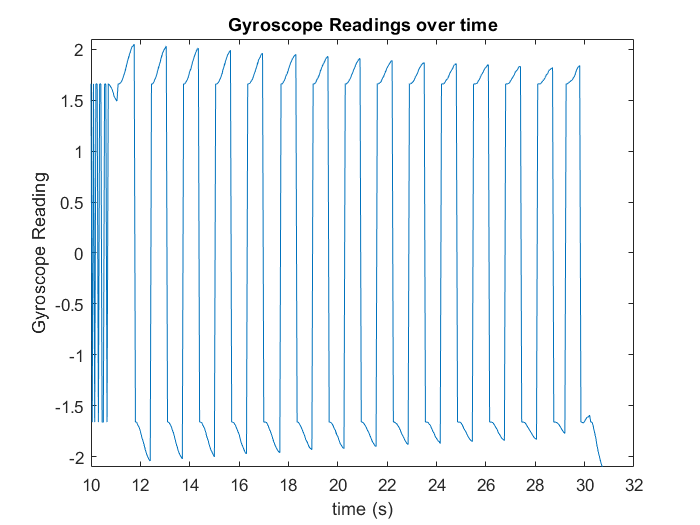

% Load and plot frequency calibration data
frequency_calibration_data = readmatrix("new_gyro_calibration.csv");

clf;
gyro_time = 0.05*[1:length(frequency_calibration_data)];
plot(gyro_time, frequency_calibration_data);
title("Gyroscope Readings over time")
xlim([10, 32]); ylim([-2.1, 2.1]);
xlabel("time (s)"); ylabel("Gyroscope Reading");


% Calculate natural frequency of first 
period = 1.3;                       % measured length of cycle from graph (seconds)
freq = 1/period;                    % Hz
Wn = freq*2*pi;                     % rad/s
L_eff = 9.81/(Wn^2);                % meters

Functions for Making Curve Fit Plots:

function [fitresult, gof] = createLWheelFit(wheel_time, l_wheel)
%CREATEFIT(WHEEL_TIME,L_WHEEL)
%  Create a fit.
%
%  Data for 'Left Wheel Calibration' fit:
%      X Input : wheel_time
%      Y Output: l_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Mar-2023 15:01:44


%% Fit: 'Left Wheel Calibration'.
[xData, yData] = prepareCurveData( wheel_time, l_wheel );

% Set up fittype and options.
ft = fittype( '(K*300)*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.157613081677548 0.964888535199277];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
clf;
figure( 'Name', 'left wheel fit' );
h = plot( fitresult, xData, yData );
title('Measured Left Wheel Velocity over Time');
legend( h, 'left wheen velocity', 'left wheel fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time (s)', 'Interpreter', 'none' );
ylabel( 'measured left wheel velocity (m/s)', 'Interpreter', 'none' );
grid on

end



function [fitresult, gof] = createRWheelFit(wheel_time, r_wheel)
%CREATEFIT(WHEEL_TIME,R_WHEEL)
%  Create a fit.
%
%  Data for 'Right Wheel Calibration' fit:
%      X Input : wheel_time
%      Y Output: r_wheel
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Mar-2023 15:04:09


%% Fit: 'Right Wheel Calibration'.
[xData, yData] = prepareCurveData( wheel_time, r_wheel );

% Set up fittype and options.
ft = fittype( '(K*300)*(1-exp(-(1/T)*x))', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.970592781760616 0.957166948242946];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
clf;
figure( 'Name', 'right wheel fit' );
h = plot( fitresult, xData, yData );
title('Measured Right Wheel Velocity over Time');
legend( h, 'right wheel velocity', 'right wheel fit', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'time (s)', 'Interpreter', 'none' );
ylabel( 'measured right wheel velocity (m/s)', 'Interpreter', 'none' );
grid on

end